% left = imread("Test Images\Snipped\A\A3.jpg");
% right = imread("Test Images\Snipped\A\A17.jpg");
% [final_slope, final_length, final_confidence] = custom_sift(left, right, 8, false);
[a,b] = meshgrid(5,1:20)

a =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


b =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


a = reshape(a,[],1);
b = reshape(b,[],1);
confidences = zeros(20,1);
thresh = 0.008;
for i=1:20
    left = imread("Test Images\Snipped\B\B"+a(i)+".jpg");
    right = imread("Test Images\Snipped\B\B"+b(i)+".jpg");
    [final_slope, final_length, final_confidence] = custom_sift(left, right, 8, true);
    confidences(i) = final_confidence;
    if final_confidence>thresh
        disp(string(a(i))+string(b(i)))
        disp(final_confidence)
    end
end

515


    0.0147



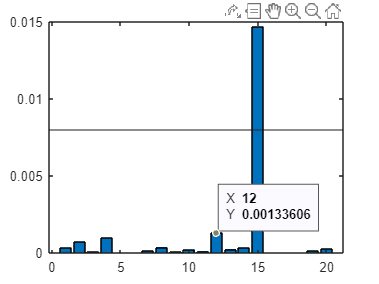

figure;
bar(confidences)
yline(thresh)